%% step1_gen_data.m
clc; clear; close all;

% =========================================================================
% 1. 读取输入图像并设置分辨率为 256x256
% =========================================================================
img_raw = imread('C:\Users\jingzifu\Desktop\camera_man.jpg'); % 替换为你自己的图片路径

if size(img_raw, 3) == 1
    img_rgb = cat(3, img_raw, img_raw, img_raw);
else
    img_rgb = img_raw;
end

WIDTH           = 256;   % 图像宽度
HEIGHT          = 256;   % 图像高度
SOBEL_THRESHOLD = 60;    % 需与 Verilog 中的 SOBEL_THRESHOLD 保持一致

img_rgb = imresize(img_rgb, [HEIGHT, WIDTH]);

% =========================================================================
% 2. 导出为 Verilog 可读的 24-bit RGB 文本 (R[23:16], G[15:8], B[7:0])
% =========================================================================
fid = fopen('src_img.txt', 'w');
if fid == -1
    error('无法创建 src_img.txt，请检查当前目录写入权限！');
end

for r = 1:HEIGHT
    for c = 1:WIDTH
        R = img_rgb(r, c, 1);
        G = img_rgb(r, c, 2);
        B = img_rgb(r, c, 3);
        fprintf(fid, '%02X%02X%02X\n', R, G, B);
    end
end
fclose(fid);
fprintf('成功生成 src_img.txt (分辨率: %dx%d)\n', WIDTH, HEIGHT);

成功生成 src_img.txt (分辨率: 256x256)


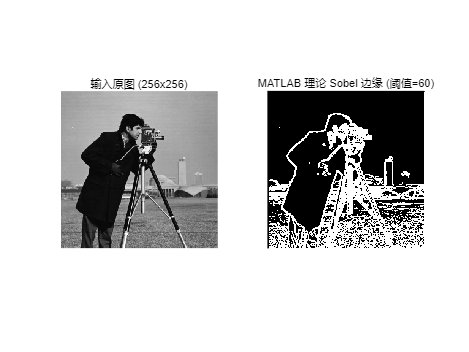


% =========================================================================
% 3. 生成 MATLAB 黄金参考图 (精确复现 FPGA 硬件逻辑)
% =========================================================================
% 步骤 A: 提取 Y 灰度分量 (与硬件 RGB888_YCbCr444 对齐)
img_ycbcr = rgb2ycbcr(img_rgb);
Y = double(img_ycbcr(:,:,1));

% 步骤 B: 定义 3x3 Sobel 卷积核
% Gx 核 (检测垂直边缘)
hx = [-1  0  1; 
      -2  0  2; 
      -1  0  1];
% Gy 核 (检测水平边缘)
hy = [ 1  2  1; 
       0  0  0; 
      -1 -2 -1];

% 步骤 C: 2D 卷积计算梯度 (采用与硬件一致的 0 边界填充)
Gx = conv2(Y, hx, 'same');
Gy = conv2(Y, hy, 'same');

% 步骤 D: 曼哈顿距离求梯度幅值: Mag = |Gx| + |Gy|
Mag = abs(Gx) + abs(Gy);

% 步骤 E: 阈值二值化 (边缘填 255/白色，背景填 0/黑色)
edge_bin = uint8((Mag >= SOBEL_THRESHOLD) * 255);

% 消除前两行和前两列的边界（与硬件消边对齐）
edge_bin(1:2, :) = 0;
edge_bin(:, 1:2) = 0;

% 转换为 24-bit RGB 图像方便对比展示
img_golden = cat(3, edge_bin, edge_bin, edge_bin);

% 保存并显示对比图
imwrite(img_golden, 'matlab_golden.png');

figure('Name', '输入原图 vs MATLAB理论 Sobel 效果');
subplot(1, 2, 1); 
imshow(img_rgb); 
title(sprintf('输入原图 (%dx%d)', WIDTH, HEIGHT));

subplot(1, 2, 2); 
imshow(img_golden); 
title(sprintf('MATLAB 理论 Sobel 边缘 (阈值=%d)', SOBEL_THRESHOLD));